求解安装TMD后的响应

clc;clear;close all % 清除记录
addpath("函数\")

读入ANSYS质量刚度矩阵

% 读取梁桥模型

% 将ANSYS中的稀疏矩阵处理为完全矩阵
% Handling sparse matrices in ANSYS as full matrices 导入ANSYS MCK矩阵
% Import MCK matrix from ANSYS
hb_to_mm ('KMatrix.matrix', 'K.txt');
hb_to_mm ('MMatrix.matrix', 'M.txt');
% hb_to_mm ('CMatrix.matrix', 'C.txt');

%map the node and matrix from the KMatrix.mapping and MMatrix.mapping
Kdata = importdata('K.txt').data;
Kmatrix = zeros(Kdata(1, 1), Kdata(1, 2));

for i = 2:size(Kdata, 1)
    Kmatrix(Kdata(i, 1), Kdata(i, 2)) = Kdata(i, 3);
end

Mdata = importdata('M.txt').data;
Mmatrix = zeros(Mdata(1, 1), Mdata(1, 2));

for i = 2:size(Mdata, 1)
    Mmatrix(Mdata(i, 1), Mdata(i, 2)) = Mdata(i, 3);
end

% Cdata = importdata('C.txt').data;
% Cmatrix_DP = zeros(Cdata(1, 1), Cdata(1, 2));
%
% for i = 2:size(Cdata, 1)
%     Cmatrix_DP(Cdata(i, 1), Cdata(i, 2)) = Cdata(i, 3);
% end

% 还原对角线以上元素，使之为对称阵, ANSYS只给出下三角矩阵
% Restore the elements above the diagonal to make it a symmetric matrix, ANSYS only gives the lower triangular matrix
K = diag(diag(Kmatrix) / 2) + Kmatrix - diag(diag(Kmatrix));
K = K + K';
M = diag(diag(Mmatrix) / 2) + Mmatrix - diag(diag(Mmatrix));
M = M + M';
% C_exp = diag(diag(Cmatrix_DP) / 2) + Cmatrix_DP - diag(diag(Cmatrix_DP));
% C_exp = C_exp + C_exp';
% C =C_exp;

模态矩阵计算

% 导入质量刚度矩阵
matrix=load('matrix.mat');
K=matrix.K;
M=matrix.M;

calmodes = 5; %考虑模态数 Consider the number of modes
[eig_vec, eig_val] = eigs(K, M, calmodes, 'SM');

[nfdof, nfdof] = size(eig_vec);

for j = 1:nfdof
    mnorm = sqrt(eig_vec(:, j)' * M * eig_vec(:, j));
    eig_vec(:, j) = eig_vec(:, j) / mnorm; %振型质量归一化 Mode shape mass normalization
end

for j = 1:nfdof
    m_modal(j) = sqrt(eig_vec(:, j)' * M * eig_vec(:, j));
end

[omeg, w_order] = sort(sqrt(diag(eig_val)));
mode_vec = eig_vec(:, w_order);
Freq = omeg / (2 * pi);


for k1 = 1:calmodes
    MM_eq(k1,k1)=P_eq(k1, mode_vec, M); %P=parameters
end

for k1 = 1:calmodes
    KK_eq(k1,k1)=P_eq(k1, mode_vec, K); %P=parameters
end


设置TMD参数

从函数读入计算完成的模态
第一阶模态质量比0.0072412%
Elapsed time is 0.008307 seconds.
Elapsed time is 2.677665 seconds.


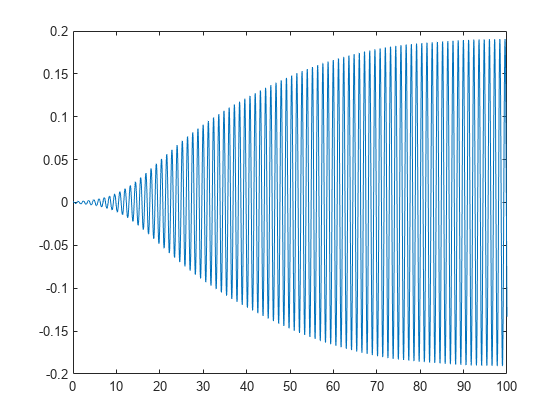

    ModeNumber     Umax      MaxDisplacement
    __________    _______    _______________

        1          400.89         0.19068   
        2          1.6971      0.00084355   
        3         0.47065      0.00026076   
        4         0.20012      9.8171e-05   
        5         0.10202      6.9008e-05   



dis1 = 0.1907

mass_six_span=10007779.7;
mu=1/100;
mTMD=mass_six_span*mu;
nTMD=1;
Ftmds = 0.8:0.01:1.2;
zetaTMDs=0.05:0.002:0.1;
omegatmds = 2 * pi * Ftmds;
% cTMD = [2 * mTMD(1) * omegatmds * 0.05];
% disp(cTMD)
% 计算桥面节点的振型向量
KMmapping = importmappingmatrix('KMatrix.mapping');
UYNode=sort(KMmapping.Node(KMmapping.DOF == 'UY'));

nodeondeck = importdata('nodeondeck.txt');
nodegap = importdata('nodegap.txt');
nodeondecknew=[];
intalledlocation=[];
for k1=1:length(nodeondeck)
    if mod(k1,5)==0
        nodeondecknew=[nodeondecknew nodeondeck(k1)];
        intalledlocation=[intalledlocation nodegap(k1)];
    end
end


mode_number=1;
ifcalmode=3;

[Ftmds_M,zetaTMDs_M,nodeondeck_M]=ndgrid(Ftmds,zetaTMDs,nodeondecknew);

variables = [Ftmds_M(:),zetaTMDs_M(:),nodeondeck_M(:)];
numIterations=size(variables,1);
%    ppm = ParforProgressbar(size(variables,1));
% for k1 = 1:numIterations
for k1 = 1:1

    zetaTMD=variables(k1,2);
    omegaTMD=variables(k1,1)*2*pi;
    nodeTMD=variables(k1,3);

    dis1(k1)=CalData_Polynomial_withTMD_multidegree(nTMD,mTMD,zetaTMD,omegaTMD,nodeTMD,mode_number,ifcalmode,MM_eq,KK_eq,calmodes,eig_val,eig_vec)

          % do some parallel computation
      pause(100/numIterations);
      % increment counter to track progress
%       ppm.increment();
end

% dis(1:numIterations)=dis1(1)

dis =     0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907    0.1907


results=[variables,dis'];
save result


## 下一节

% Create optimization variables
zetaTMD3 = optimvar("zetaTMD","LowerBound",0.05,"UpperBound",0.1);
omegaTMD2 = optimvar("omegaTMD","LowerBound",5,"UpperBound",8);
nodeTMD2 = optimvar("nodeTMD","Type","integer","LowerBound",1001,"UpperBound",...
    1406);

% Set initial starting point for the solver
initialPoint2.zetaTMD = zeros(size(zetaTMD3));
initialPoint2.omegaTMD = zeros(size(omegaTMD2));
initialPoint2.nodeTMD = zeros(size(nodeTMD2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@CalData_Polynomial_withTMD_multidegree,...
    nTMD,mTMD,zetaTMD3,omegaTMD2,nodeTMD2,mode_number);

% Set nondefault solver options
options2 = optimoptions("ga","Display","iter","UseParallel",true,"PlotFcn",...
    ["gaplotdistance","gaplotgenealogy","gaplotselection",...
    "gaplotscorediversity","gaplotscores","gaplotstopping","gaplotmaxconstr",...
    "gaplotbestf","gaplotbestindiv","gaplotexpectation","gaplotrange"]);

% Display problem information
show(problem);

% Clear variables
clearvars zetaTMD3 omegaTMD2 nodeTMD2 initialPoint2 options2

所需函数

function result = P_eq(mode, temp_vec, Matrix)
    vec = temp_vec(:, mode);
    result = vec' * Matrix * vec;
end